# **Esercitzione n*3 - Stima modelli ingresso uscita**

## Descrizione del problema

E' stato condotto un esperimento per valutare la cinetica del C-peptide (un peptide secreto insieme all'insulina) in 7 soggetti misurando la risposta ad un bolo di C-peptide sintetico. L'esperimento prevede una misura al tempo 0 (prima del bolo) per determinare il valore della concentrazione basale. La misura effettuata al minuto 1 non e' da considerare (e deve essere trascurata nell'identificazione del modello) in quanto ci sono buone ragioni per affermare cha a quel tempo la concentrazione plasmatica non e' uniforme (la sostanza non si e' ancora distribuita nell'intero compartimento plasmatico - problemi di mescolamento). Le misure di concentrazione sono affette da un errore di misura caratterizzato da un CV del 4%. Come esercizio e in via esploratoria, identificare su i dati di almeno un soggetto i modelli a 1,2,3 esponenziali utilizzandp la tecnica dei minimi quadrati e dei minimi quadrati pesati (con peso pari all'inverso della varianza dell'errore di misura). 

clearvars;
close all;
clc;

## Lettura dei dati 

I dati sono relativi a 7 soggetti diversi e contenuti nei file` DatiCPSog1.dat`, `DatiCPSog2.dat, ecc.`

% Importazione dei dati 
d_sog1 = importdata("DatiCPsog1.dat");
d_sog2 = importdata("DatiCPsog2.dat");
d_sog3 = importdata("DatiCPsog3.dat");
d_sog4 = importdata("DatiCPsog4.dat");
d_sog5 = importdata("DatiCPsog5.dat");
d_sog6 = importdata("DatiCPsog6.dat");
d_sog7 = importdata("DatiCPsog7.dat");

Dal momento che i dati letti attraverso la funzione `importdata `sono organizzati in una struttura che richiederebbe molte operazioni, si memorizzano le informazioni in semplici array. Tale procedura consente di effettuare in agilita' le successive operazioni di data cleaning.

% Data retrieval
dose1 = str2num(d_sog1.textdata{1,2});
t1 = str2num(cell2mat(d_sog1.textdata(4:end,1)));
c1 = str2num(cell2mat(d_sog1.textdata(4:end,2)));

dose2 = str2num(d_sog2.textdata{1,2});
t2 = str2num(cell2mat(d_sog2.textdata(4:end,1)));
c2 = str2num(cell2mat(d_sog2.textdata(4:end,2)));

dose3 = str2num(d_sog3.textdata{1,2});
t3 = str2num(cell2mat(d_sog3.textdata(4:end,1)));
c3 = str2num(cell2mat(d_sog3.textdata(4:end,2)));

dose4 = str2num(d_sog4.textdata{1,2});
t4 = str2num(cell2mat(d_sog4.textdata(4:end,1)));
c4 = str2num(cell2mat(d_sog4.textdata(4:end,2)));

dose5 = str2num(d_sog5.textdata{1,2});
t5 = str2num(cell2mat(d_sog5.textdata(4:end,1)));
c5 = str2num(cell2mat(d_sog5.textdata(4:end,2)));

dose6 = str2num(d_sog6.textdata{1,2});
t6 = str2num(cell2mat(d_sog6.textdata(4:end,1)));
c6 = str2num(cell2mat(d_sog6.textdata(4:end,2)));

dose7 = str2num(d_sog7.textdata{1,2});
t7 = str2num(cell2mat(d_sog7.textdata(4:end,1)));
c7 = str2num(cell2mat(d_sog7.textdata(4:end,2)));


## Analisi visiva

Prima di effettuare il fitting dei possibili modelli a 1,2,3 esponenziali con i minimi quadrati o minimi quadrati pesati, si effettua un'analisi visiva dei dati relativi ai 7 soggetti dello studio. Il grafico riporta esattamente le misurazioni effettuate prima e dopo la somministrazione del bolo. La misura corrispondente al minuto 0 rappresenta la contrazione di C-peptide basale, mentre quelle successive sono relative all'effetto della somministrazione. Tuttavia ai fini del fitting dei diversi modelli, la misura dopo il primo minuto deve essere scartata poiche' la concentrazione plasmatica non e' uniforme. 

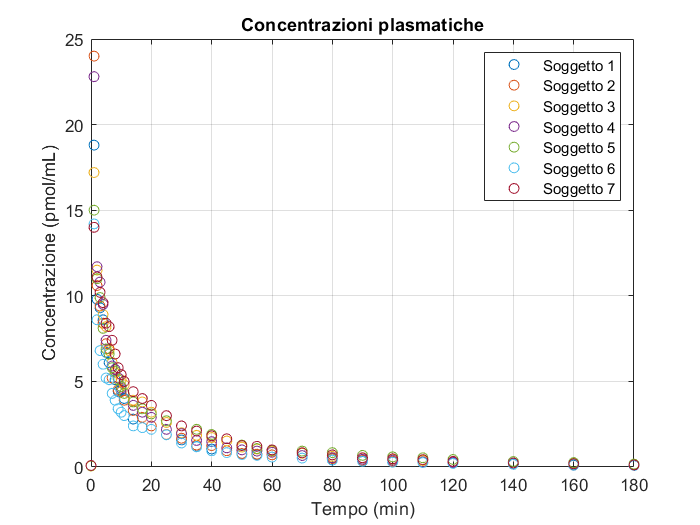

% Plot concentrazioni plasmatiche
figure(1);
plot(t1,c1,"o",t2,c2,"o",t3,c3,"o",t4,c4,"o",t5,c5,"o",t6,c6,"o",t7,c7,"o"),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Concentrazioni plasmatiche"), legend("Soggetto 1","Soggetto 2","Soggetto 3","Soggetto 4", ...
"Soggetto 5","Soggetto 6","Soggetto 7")

Eliminazione della concentrazione basale e delle misure non necessarie nel fitting.

cb = [c1(1),c2(1),c3(1),c4(1),c5(1),c6(1),c7(1)];

c1 = c1 - c1(1); % Eliminazione concentrazione basale
c1 = c1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo
t1 = t1(3:end);  % Eliminazione misura concentrazione basale e minuto successivo (tempo)
c2 = c2 - c2(1);
c2 = c2(3:end);
t2 = t2(3:end);
c3 = c3 - c3(1);
c3 = c3(3:end);
t3 = t3(3:end);
c4 = c4 - c4(1);
c4 = c4(3:end);
t4 = t4(3:end);
c5 = c5 - c5(1);
c5 = c5(3:end);
t5 = t5(3:end);
c6 = c6 - c6(1);
c6 = c6(3:end);
t6 = t6(3:end);
c7 = c7 - c7(1);
c7 = c7(3:end);
t7 = t7(3:end);

## Stima dei parametri con Minimi Quadrati (LS) e Minimi Quadrati Pesati (WLS)

Il metodo ai Minimi Quadrati (*Least Squares*) consente di trovere i parametri `p` del modello tali che la discrepanza tra i dati *z* e le predizioni del modello *h(ti,p)* sia minima. Per far questo si utilizza il seguente funzionale di costo: 


$$J\left(p\right)=\sum_{i=1}^N {\left(z_i -y_i \right)}^2 =\sum_{i=1}^N {\left(z_i -h\left(t_i \;,p\right)\right)}^2 =\sum_{i=1}^N {e_i }^2$$
 

Bisogna percio' risolvere il seguente problema di ottimizzazione:


$$\hat{p_{\mathrm{LS}} } =\mathrm{argmin}\left(J\left(p\right)\right)$$


In modo analogo si definisce il funzionale di costo per i Minimi Quadrati Pesati (*Weighted Least Squares*) considerando la matrice dei pesi *W = diag(w1,w2,...,wn)*:


$$J_W \left(p\right)={|\left|z-H\left(p\right)\right|\left|\right.}^2 =\sum_{i=1}^N {{w_i e}_i }^2 \;\left(p\right)$$


in cui l'errore *ei* ha peso differente sei i *wi *sono diversi tra loro. Ancora una volta e' necessario risolvere il seguente problema di ottimizzazione: 


$$\hat{p_{\mathrm{WLS}} } =\mathrm{argmin}\left(J_W \left(p\right)\right)\;$$


Quando la funzione h che determina l'uscita predetta dal modello non e' lineare, il problema non e' risolvibile in forma chiusa ed e' necessario ricorrere a metodi iterativi (in Matlab si usa la funzione `lsqnonlin`). 

## Fitting di modelli ingresso uscita a 1,2,3 esponenziali

Segue il fitting dei modelli ingresso uscita con Minimi Quadrati e Minimi Quadrati Pesati per uno specifico paziente.

selectedSogg = "Soggetto3"; % Selezione del soggetto 
switch selectedSogg
    case "Soggetto1"
        c = c1;
        t = t1;
        cb = cb(1);
    case "Soggetto2"
        c = c2;
        t = t2;
        cb = cb(2);
    case "Soggetto3"
        c = c3;
        t = t3;
        cb = cb(3);
    case "Soggetto4"
        c = c4;
        t = t4;
        cb = cb(4);
    case "Soggetto5"
        c = c5;
        t = t5;
        cb = cb(5);
    case "Soggetto6"
        c = c6;
        t = t6;
        cb = cb(6);
    case "Soggetto7"
        c = c7;
        t = t7;
        cb = cb(7);
end

### Fitting modello ingresso uscita mono-esponenziale con LS e WLS

Come precedentemente detto i parametri *p* ottimali del modello si ottengono risolvendo i problemi di ottimizzazione tramite la funzione `lsqnonlin.` 

Nota: 

- `@funzionale` : handle della funzione che definisce il funzionale di costo J(p);

- `p0` : parametri iniziali per l'algoritmo di ricerca;

- `options` : opzioni di visualizzazione; 

- `t`, `c`, `1` : sono i parametri della funzione `funzionale. `

#### `LS - Modello monoesponenziale`

p0 = [18.72,0.7]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x1_ls,resnorm1_ls,residual1_ls,~,~,~,jacobian1_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,1); % LS 1-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         473.986                           200
     1          6         473.986             10            200      
     2          9         473.986            2.5            200      
     3         12         224.341          0.625        3.5e+03      
     4         15         55.4384           1.25            739      
     5         18         23.3805            2.5           8.95      
     6         21         16.2085        2.54078            116      
     7         24         15.3638       0.370504           28.4      
     8         27         15.2645       0.181572           11.7      
     9         30         15.2492      0.0689558           4.63      
    10         33         15.2468      0.0274662           1.86      
    11         36         15.2464      0.0110072          0.746      
    12         39         15.246

Seguono plot in scala naturale e in scala logaritmica del fit.

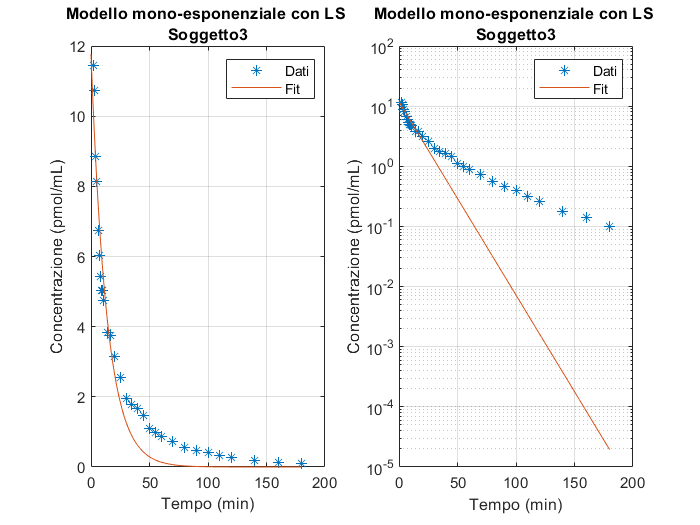

figure(2);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x1_ls(1)*exp(-x1_ls(2)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x1_ls(1)*exp(-x1_ls(2)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello mono-esponenziale con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 1-exp: A = ",num2str(x1_ls(1))," alpha = ",num2str(x1_ls(2))]); % Stampa dei parametri del fitting

    "Parametri LS 1-exp: A = "    "11.7731"    " alpha = "    "0.073962"



Analisi dei residui.

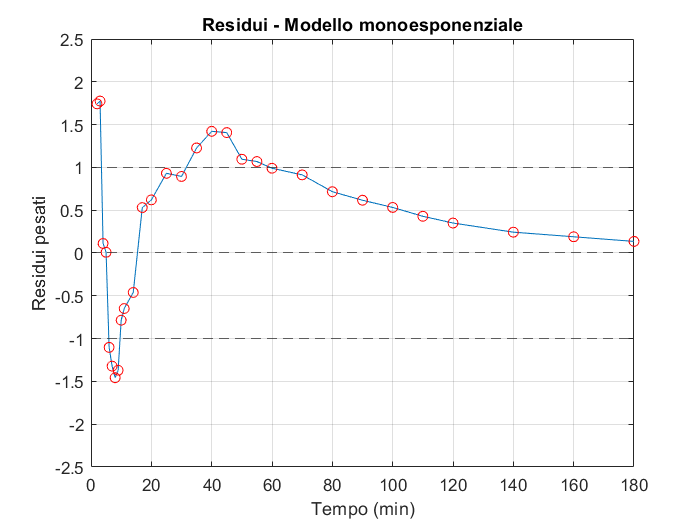

figure(3);
alpha_cap = resnorm1_ls/(length(c)-2);
plot(t,residual1_ls./sqrt(alpha_cap),"-o","MarkerIndices",1:1:length(residual1_ls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello monoesponenziale"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime e' necessario calcolare la matrice di correlazione a partire dalla matrice di covarianza. L'errore di stima e' definito come $\overset{~}{p} =p-\hat{p}$ a cui corrisponde la seguente matrice di covarianza:


$$\Sigma_{\overset{~}{p} } =\mathrm{cov}\left(\overset{~}{p} \right)=E\left\lbrack \overset{~}{p} {\overset{~}{p} }^T \right\rbrack =\mathrm{cov}\left(\hat{p} \right)$$


Poiche' ci si trova nel caso non lineare questa puo' essere calcolata come $\Sigma_{\overset{~}{p} } ={\left(S^T {\Sigma^{-1} }_v S\right)}^{-1}$ in cui la matrice S rappresenta lo jacobiano (calcolato nei parametri ottimi). In questo caso la matrice ${\Sigma^{-1} }_v$ e' omessa nel codice perche' il suo contributo e' implicitamente definito. 

L'entrata $r_{\mathrm{ij}}$ della matrice di correlazione sara' data cosi' dalla formula: $r_{\mathrm{ij}} =\frac{C_{\mathrm{ij}} }{\sqrt{C_{\mathrm{ii}} *C_{\mathrm{jj}} }}$ con $C=\Sigma_{\overset{~}{p} }$.

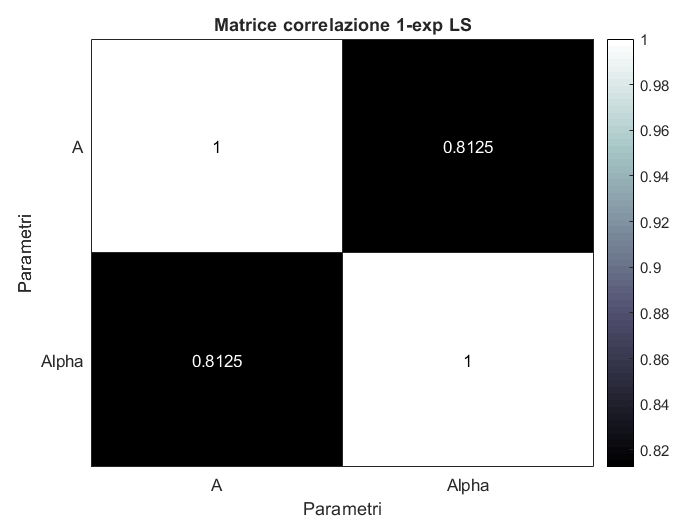

sigma_v = alpha_cap*eye(length(c));
sigma_pt1_ls = inv(full(jacobian1_ls)'*inv(sigma_v)*full(jacobian1_ls)); % Matrice di covarianza

% Matrice di correlazione
cor1_ls = zeros(length(sigma_pt1_ls));

for i = 1:length(sigma_pt1_ls)
    for j = 1:length(sigma_pt1_ls)
        cor1_ls(i,j) = sigma_pt1_ls(i,j)/sqrt(sigma_pt1_ls(i,i)*sigma_pt1_ls(j,j));
    end
end

figure(14);
xvalues = {'A','Alpha'};
yvalues = {'A','Alpha'};
h = heatmap(xvalues,yvalues,cor1_ls,"Colormap",bone);

h.Title = 'Matrice correlazione 1-exp LS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic1_ls = (resnorm1_ls+2*2)/length(c);  % AIC

% ICOMP
f1_ls = full(jacobian1_ls)'*inv(sigma_v)*full(jacobian1_ls); % Matrice informazione di Fischer
lambda_a1 = trace(f1_ls)/2;
lambda_g1 = det(f1_ls)^(1/2);
icomp1_ls = resnorm1_ls+2*(2/2*log(lambda_a1/lambda_g1));

disp(["AIC = ",num2str(aic1_ls),"ICOMP = ",num2str(icomp1_ls)]);

    "AIC = "    "0.64154"    "ICOMP = "    "23.9362"



Calcolo CV 

cv1_1_ls = 100*sqrt(sigma_pt1_ls(1,1))/x1_ls(1);
cv1_2_ls = 100*sqrt(sigma_pt1_ls(2,2))/x1_ls(2);

cv1 = [cv1_1_ls,cv1_2_ls]';
cv1_ls = table(x1_ls',cv1,'VariableNames',{'Parametri','CV'});
disp(cv1_ls);

    Parametri      CV  
    _________    ______

      11.773     5.0776
    0.073962     8.9939



#### `LS - Modello con due esponenziali`

p0 = [18.72,0.7,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x2_ls,resnorm2_ls,residual2_ls,~,~,~,jacobian2_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,2); % LS 2-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         265.306                      2.47e+03
     1         10         84.7174             10            419      
     2         15         84.7174             20            419      
     3         20         73.9865              5            204      
     4         25         63.3215              5            139      
     5         30         63.3215             10            139      
     6         35         63.3215            2.5            139      
     7         40         63.3215          0.625            139      
     8         45         63.3215        0.15625            139      
     9         50         47.7901      0.0390625            160      
    10         55         47.7901      0.0858956            160      
    11         60         39.3944      0.0195312            173      
    12         65         26.578

Seguono plot in scala naturale e in scala logaritmica del fit.

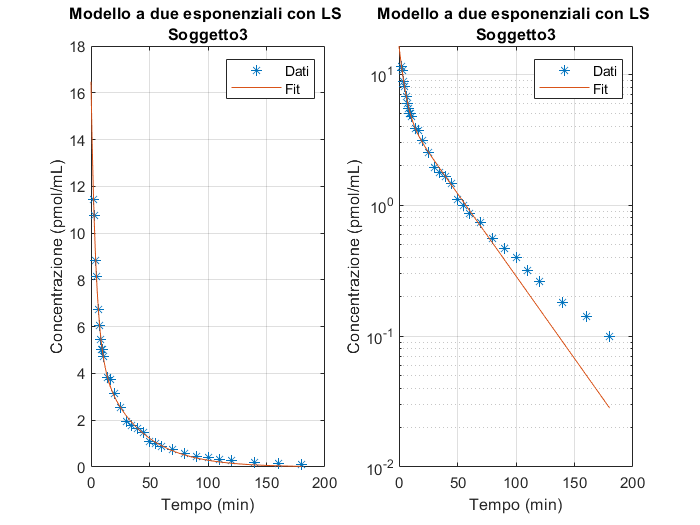

figure(4);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x2_ls(1)*exp(-x2_ls(2)*t_ls)+x2_ls(3)*exp(-x2_ls(4)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a due esponenziali con LS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x2_ls(1)*exp(-x2_ls(2)*t_ls)+x2_ls(3)*exp(-x2_ls(4)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a due esponenziali con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 2-exp: A = ",num2str(x2_ls(1))," alpha = ",num2str(x2_ls(2))," B = ",num2str(x2_ls(3))," beta = ",num2str(x2_ls(4))]); % Stampa dei parametri del fitting

    "Parametri LS 2-ex…"    "11.2254"    " alpha = "    "0.24621"    " B = "    "5.2471"    " beta = "    "0.029028"



Analisi dei residui.

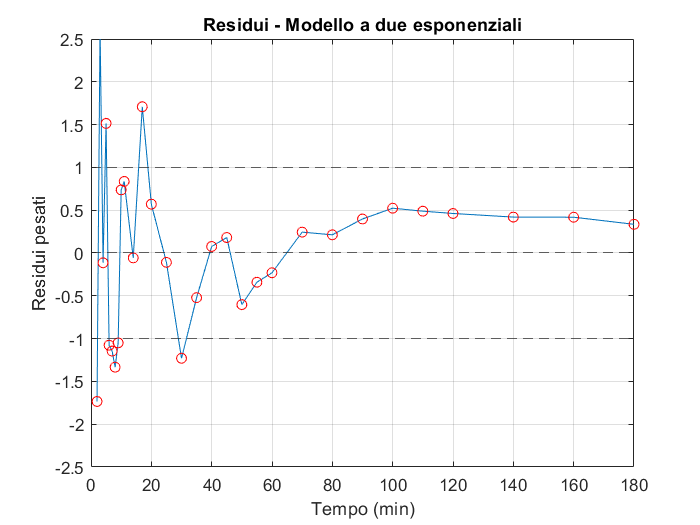

figure(5);
alpha_cap = resnorm2_ls/(length(c)-4);
plot(t,residual2_ls./sqrt(alpha_cap),"-o","MarkerIndices",1:1:length(residual2_ls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a due esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime numeriche dei parametri, calcolo la matrice di correlazione (a partire dalla matrice di covarianza).

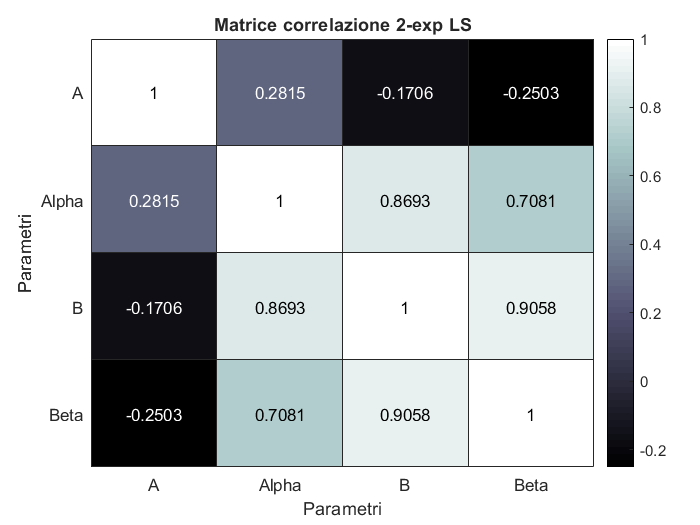

sigma_v = alpha_cap*eye(length(c));
sigma_pt2_ls = inv(full(jacobian2_ls)'*inv(sigma_v)*full(jacobian2_ls)); % Matrice di covarianza

% Matrice di correlazione
cor2_ls = zeros(length(sigma_pt2_ls));

for i = 1:length(sigma_pt2_ls)
    for j = 1:length(sigma_pt2_ls)
        cor2_ls(i,j) = sigma_pt2_ls(i,j)/sqrt(sigma_pt2_ls(i,i)*sigma_pt2_ls(j,j));
    end
end

figure(15);
xvalues = {'A','Alpha','B','Beta'};
yvalues = {'A','Alpha','B','Beta'};
h = heatmap(xvalues,yvalues,cor2_ls,"Colormap",bone);

h.Title = 'Matrice correlazione 2-exp LS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic2_ls = (resnorm2_ls+2*4)/length(c);  % AIC

% ICOMP
f2_ls = full(jacobian2_ls)'*inv(sigma_v)*full(jacobian2_ls); % Matrice informazione di Fischer
lambda_a2 = trace(f2_ls)/4;
lambda_g2 = det(f2_ls)^(1/4);
icomp2_ls = resnorm2_ls+2*(4/2*log(lambda_a2/lambda_g2));

disp(["AIC = ",num2str(aic2_ls),"ICOMP = ",num2str(icomp2_ls)]);

    "AIC = "    "0.30641"    "ICOMP = "    "24.1323"



Calcolo CV.

cv2_1_ls = 100*sqrt(sigma_pt2_ls(1,1))/x2_ls(1);
cv2_2_ls = 100*sqrt(sigma_pt2_ls(2,2))/x2_ls(2);
cv2_3_ls = 100*sqrt(sigma_pt2_ls(3,3))/x2_ls(3);
cv2_4_ls = 100*sqrt(sigma_pt2_ls(4,4))/x2_ls(4);

cv2 = [cv2_1_ls,cv2_2_ls,cv2_3_ls,cv2_4_ls]';
cv2_ls = table(x2_ls',cv2,'VariableNames',{'Parametri','CV'});
disp(cv2_ls);

    Parametri      CV  
    _________    ______

      11.225     4.3422
     0.24621     9.2951
      5.2471     7.9303
    0.029028     8.1927



#### `LS - Modello con tre esponenziali`

p0 = [18.72,0.7,20,0.1,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x3_ls,resnorm3_ls,residual3_ls,~,~,~,jacobian3_ls] = lsqnonlin(@funzionale,p0,[],[],options,t,c,3); % LS 3-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7         2713.12                      9.63e+03
     1         14         408.287             10       1.27e+03      
     2         21         408.287             20       1.27e+03      
     3         28         408.287              5       1.27e+03      
     4         35         246.035           1.25            837      
     5         42         184.827            2.5            232      
     6         49         158.807              5            162      
     7         56         158.337             10            271      
     8         63         158.337            2.5            271      
     9         70         111.706          0.625           91.1      
    10         77         103.185           1.25       3.02e+03      
    11         84         85.4118           1.25            328      
    12         91         75.333

Seguono plot in scala naturale e in scala logaritmica del fit.

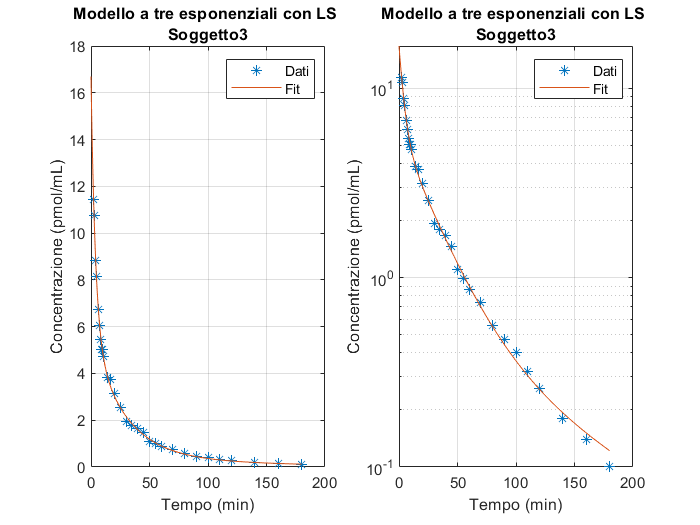

figure(10);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x3_ls(1)*exp(-x3_ls(2)*t_ls)+x3_ls(3)*exp(-x3_ls(4)*t_ls)+x3_ls(5)*exp(-x3_ls(6)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a tre esponenziali con LS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x3_ls(1)*exp(-x3_ls(2)*t_ls)+x3_ls(3)*exp(-x3_ls(4)*t_ls)+x3_ls(5)*exp(-x3_ls(6)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a tre esponenziali con LS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 3-exp: A = ",num2str(x3_ls(1))," alpha = ",num2str(x3_ls(2))," B = ",num2str(x3_ls(3))," beta = ",num2str(x3_ls(4)), ...
      " C = ",num2str(x3_ls(5))," gamma = ",num2str(x3_ls(6))]); % Stampa dei parametri del fitting

  Columns 1 through 9

    "Parametri LS 3-ex…"    "10.9059"    " alpha = "    "0.26444"    " B = "    "5.2365"    " beta = "    "0.036811"    " C = "

  Columns 10 through 12

    "0.5546"    " gamma = "    "0.0087414"



Analisi dei residui.

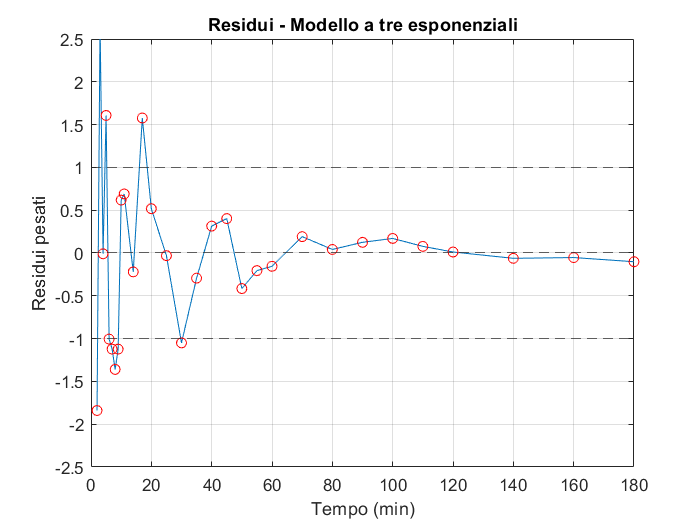

figure(11);
alpha_cap = resnorm3_ls/(length(c)-6);
plot(t,residual3_ls./sqrt(alpha_cap),"-o","MarkerIndices",1:1:length(residual3_ls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a tre esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime numeriche dei parametri, calcolo la matrice di correlazione (a partire dalla matrice di covarianza).

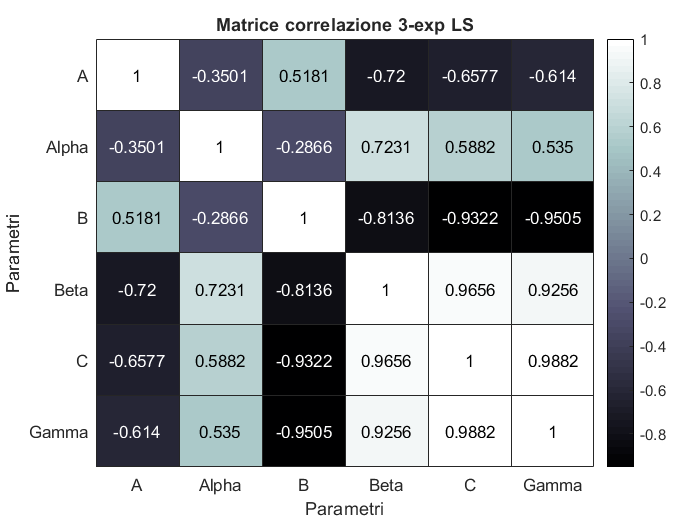

sigma_v = alpha_cap*eye(length(c));
sigma_pt3_ls = inv(full(jacobian3_ls)'*inv(sigma_v)*full(jacobian3_ls)); % Matrice di covarianza

% Matrice di correlazione
cor3_ls = zeros(length(sigma_pt3_ls));

for i = 1:length(sigma_pt3_ls)
    for j = 1:length(sigma_pt3_ls)
        cor3_ls(i,j) = sigma_pt3_ls(i,j)/sqrt(sigma_pt3_ls(i,i)*sigma_pt3_ls(j,j));
    end
end

figure(16);
xvalues = {'A','Alpha','B','Beta','C','Gamma'};
yvalues = {'A','Alpha','B','Beta','C','Gamma'};
h = heatmap(xvalues,yvalues,cor3_ls,"Colormap",bone);

h.Title = 'Matrice correlazione 3-exp LS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic3_ls = (resnorm3_ls+2*6)/length(c);  % AIC

% ICOMP
f3_ls = full(jacobian3_ls)'*inv(sigma_v)*full(jacobian3_ls); % Matrice informazione di Fischer
lambda_a3 = trace(f3_ls)/6;
lambda_g3 = det(f3_ls)^(1/6);
icomp3_ls = resnorm3_ls+2*(6/2*log(lambda_a3/lambda_g3));

disp(["AIC = ",num2str(aic3_ls),"ICOMP = ",num2str(icomp3_ls)]);

    "AIC = "    "0.43709"    "ICOMP = "    "37.2035"



Calcolo CV.

cv3_1_ls = 100*sqrt(sigma_pt3_ls(1,1))/x3_ls(1);
cv3_2_ls = 100*sqrt(sigma_pt3_ls(2,2))/x3_ls(2);
cv3_3_ls = 100*sqrt(sigma_pt3_ls(3,3))/x3_ls(3);
cv3_4_ls = 100*sqrt(sigma_pt3_ls(4,4))/x3_ls(4);
cv3_5_ls = 100*sqrt(sigma_pt3_ls(5,5))/x3_ls(5);
cv3_6_ls = 100*sqrt(sigma_pt3_ls(6,6))/x3_ls(6);

cv3 = [cv3_1_ls,cv3_2_ls,cv3_3_ls,cv3_4_ls,cv3_5_ls,cv3_6_ls]';
cv3_ls = table(x3_ls',cv3,'VariableNames',{'Parametri','CV'});
disp(cv3_ls);

    Parametri      CV  
    _________    ______

       10.906     6.982
      0.26444     14.79
       5.2365    32.655
     0.036811     52.05
       0.5546    423.64
    0.0087414    322.75



#### WLS - Modello monoesponenziale

CV = 0.04;           % CV
alpha = CV^2;        % alpha
B = diag((c+cb).^2); % B
sigma_v = alpha*B;   % Matrice SigmaV
w = inv(sigma_v);    % Matrice dei pesi

p0 = [18.72,0.5]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x1_wls,resnorm1_wls,residual1_wls,~,~,~,jacobian1_wls] = lsqnonlin(@funzionalew,p0,[],[],options,t,c,1,sqrt(w)); % LS 1-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3           14441                      3.33e+03
     1          6           14441             10       3.33e+03      
     2          9           14441            2.5       3.33e+03      
     3         12           14441          0.625       3.33e+03      
     4         15         12899.6        0.15625       7.05e+03      
     5         18         12899.6       0.364086       7.05e+03      
     6         21         11558.9       0.078125       1.03e+04      
     7         24         7755.31        0.15625       7.27e+03      
     8         27            7572         0.3125       5.89e+03      
     9         30          7298.7          0.625       6.57e+03      
    10         33         6736.79           1.25       1.09e+04      
    11         36         5439.64            2.5       2.44e+04      
    12         39         2521.1

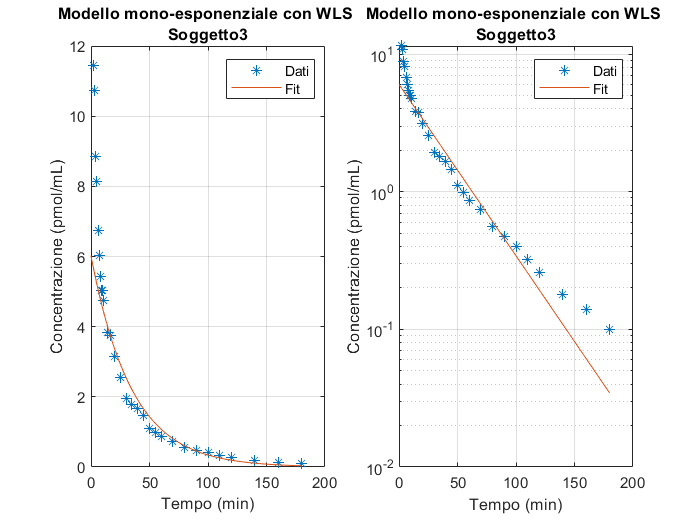

figure(6);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x1_wls(1)*exp(-x1_wls(2)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello mono-esponenziale con WLS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x1_wls(1)*exp(-x1_wls(2)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello mono-esponenziale con WLS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri WLS 1-exp: A = ",num2str(x1_wls(1))," alpha = ",num2str(x1_wls(2))]); % Stampa dei parametri del fitting

    "Parametri WLS 1-exp: A = "    "6.019"    " alpha = "    "0.028674"



Analisi dei residui.

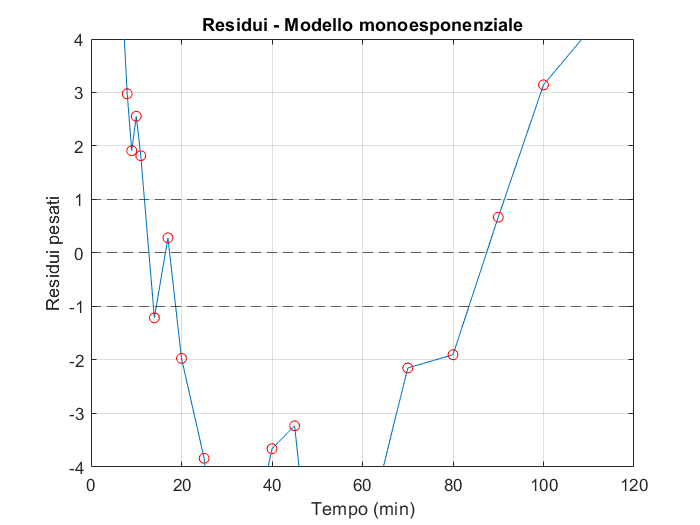

figure(7);
plot(t,residual1_wls,"-o","MarkerIndices",1:1:length(residual1_wls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-4,4]), title("Residui - Modello monoesponenziale"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime e' necessario calcolare la matrice di correlazione a partire dalla matrice di covarianza. L'errore di stima e' definito come $\overset{~}{p} =p-\hat{p}$ a cui corrisponde la seguente matrice di covarianza:


$$\Sigma_{\overset{~}{p} } =\mathrm{cov}\left(\overset{~}{p} \right)=E\left\lbrack \overset{~}{p} {\overset{~}{p} }^T \right\rbrack =\mathrm{cov}\left(\hat{p} \right)$$


Poiche' ci si trova nel caso non lineare questa puo' essere calcolata come $\Sigma_{\overset{~}{p} } ={\left(S^T {\Sigma^{-1} }_v S\right)}^{-1}$ in cui la matrice S rappresenta lo jacobiano (calcolato nei parametri ottimi). In questo caso la matrice ${\Sigma^{-1} }_v$ e' omessa nel codice perche' il suo contributo e' implicitamente definito. 

L'entrata $r_{\mathrm{ij}}$ della matrice di correlazione sara' data cosi' dalla formula: $r_{\mathrm{ij}} =\frac{C_{\mathrm{ij}} }{\sqrt{C_{\mathrm{ii}} *C_{\mathrm{jj}} }}$ con $C=\Sigma_{\overset{~}{p} }$.

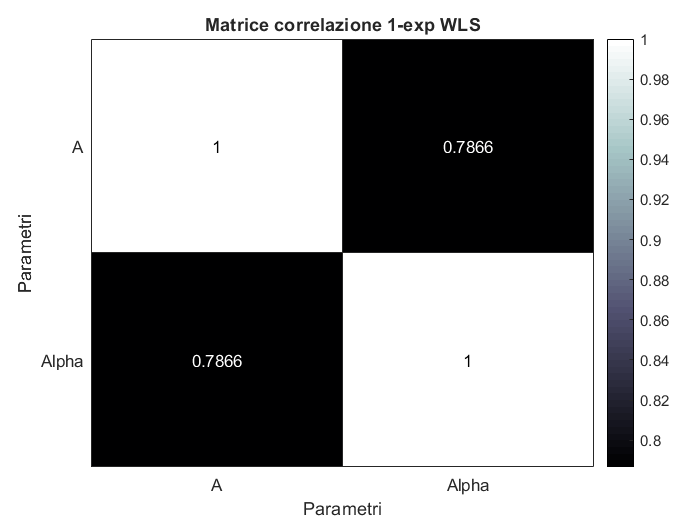

sigma_pt1_wls = inv(full(jacobian1_wls)'*full(jacobian1_wls)); % Matrice di covarianza

% Matrice di correlazione
cor1_wls = zeros(length(sigma_pt1_wls));

for i = 1:length(sigma_pt1_wls)
    for j = 1:length(sigma_pt1_wls)
        cor1_wls(i,j) = sigma_pt1_wls(i,j)/sqrt(sigma_pt1_wls(i,i)*sigma_pt1_wls(j,j));
    end
end

figure(17);
xvalues = {'A','Alpha'};
yvalues = {'A','Alpha'};
h = heatmap(xvalues,yvalues,cor1_wls,"Colormap",bone);

h.Title = 'Matrice correlazione 1-exp WLS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic1_wls = (resnorm1_wls+2*2)/length(c);  % AIC

% ICOMP
f1_wls = full(jacobian1_wls)'*full(jacobian1_wls); % Matrice informazione di Fischer
lambda_a1 = trace(f1_wls)/2;
lambda_g1 = det(f1_wls)^(1/2);
icomp1_wls = resnorm1_wls+2*(2/2*log(lambda_a1/lambda_g1));

disp(["AIC = ",num2str(aic1_wls),"ICOMP = ",num2str(icomp1_wls)]);

    "AIC = "    "37.8359"    "ICOMP = "    "1142.1221"



Calcolo CV 

cv1_1 = 100*sqrt(sigma_pt1_wls(1,1))/x1_wls(1);
cv1_2 = 100*sqrt(sigma_pt1_wls(2,2))/x1_wls(2);

cv1 = [cv1_1,cv1_2]';
cv1_wls = table(x1_wls',cv1,'VariableNames',{'Parametri','CV'});
disp(cv1_wls);

    Parametri      CV   
    _________    _______

       6.019      1.3146
    0.028674     0.89355



#### `WLS - Modello con due esponenziali`

p0 = [18.72,0.7,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x2_wls,resnorm2_wls,residual2_wls,~,~,~,jacobian2_wls] = lsqnonlin(@funzionalew,p0,[],[],options,t,c,2,sqrt(w)); % LS 2-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5         8789.54                      8.32e+03
     1         10         7944.42             10       5.85e+03      
     2         15         7944.42             20       5.85e+03      
     3         20         7726.88              5       1.48e+04      
     4         25         5737.03              5       4.72e+04      
     5         30         5737.03             10       4.72e+04      
     6         35         2960.42            2.5       4.42e+04      
     7         40         271.004              5       6.58e+04      
     8         45         113.785        2.06839            706      
     9         50         113.622      0.0552621           27.7      
    10         55         113.589      0.0387574           26.7      
    11         60         113.579      0.0206965           14.8      
    12         65         113.57

Seguono plot in scala naturale e in scala logaritmica del fit.

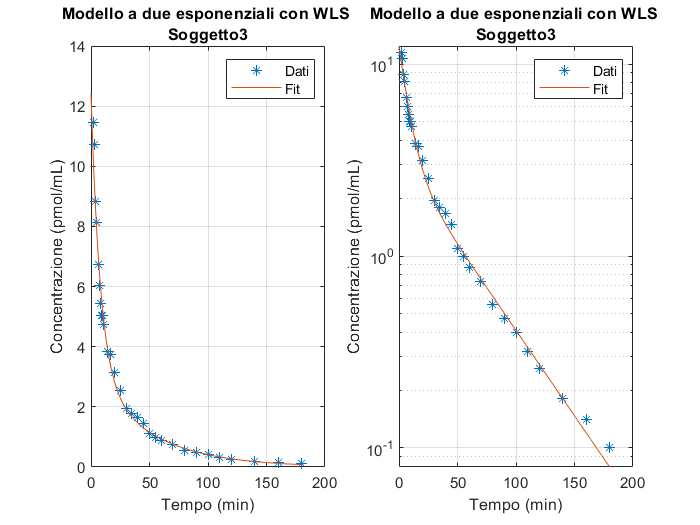

figure(8);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x2_wls(1)*exp(-x2_wls(2)*t_ls)+x2_wls(3)*exp(-x2_wls(4)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a due esponenziali con WLS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x2_wls(1)*exp(-x2_wls(2)*t_ls)+x2_wls(3)*exp(-x2_wls(4)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a due esponenziali con WLS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 2-exp: A = ",num2str(x2_wls(1))," alpha = ",num2str(x2_wls(2))," B = ",num2str(x2_wls(3))," beta = ",num2str(x2_wls(4))]); % Stampa dei parametri del fitting

    "Parametri LS 2-ex…"    "9.2471"    " alpha = "    "0.12641"    " B = "    "3.182"    " beta = "    "0.020492"



Analisi dei residui.

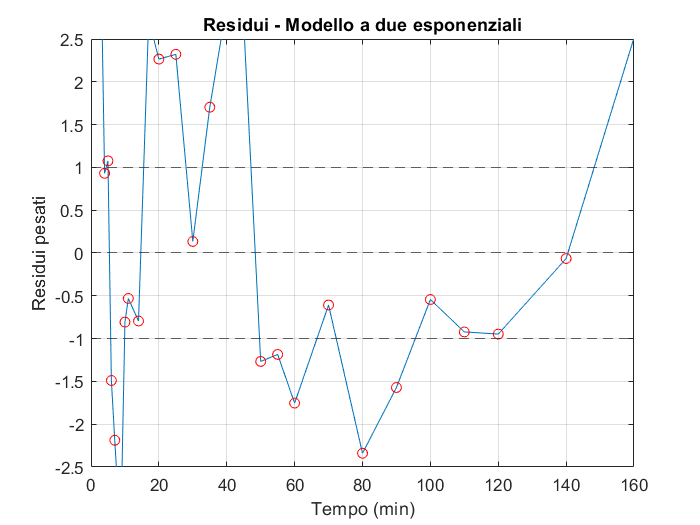

figure(9);
plot(t,residual2_wls,"-o","MarkerIndices",1:1:length(residual2_wls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a due esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime numeriche dei parametri, calcolo la matrice di correlazione (a partire dalla matrice di covarianza). 

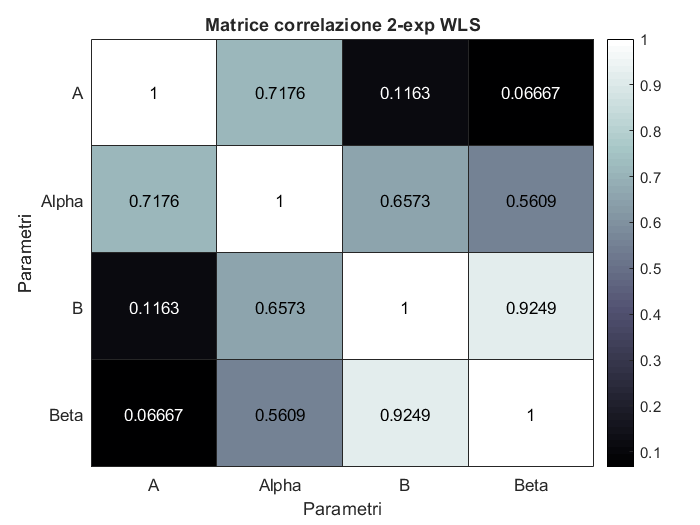

sigma_pt2_wls = inv(full(jacobian2_wls)'*full(jacobian2_wls)); % Matrice di covarianza

% Matrice di correlazione
cor2_wls = zeros(length(sigma_pt2_wls));

for i = 1:length(sigma_pt2_wls)
    for j = 1:length(sigma_pt2_wls)
        cor2_wls(i,j) = sigma_pt2_wls(i,j)/sqrt(sigma_pt2_wls(i,i)*sigma_pt2_wls(j,j));
    end
end

figure(18);
xvalues = {'A','Alpha','B','Beta'};
yvalues = {'A','Alpha','B','Beta'};
h = heatmap(xvalues,yvalues,cor2_wls,"Colormap",bone);

h.Title = 'Matrice correlazione 2-exp WLS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic2_wls = (resnorm2_wls+2*4)/length(c);  % AIC

% ICOMP
f2_wls = full(jacobian2_wls)'*full(jacobian2_wls); % Matrice informazione di Fischer
lambda_a1 = trace(f2_wls)/4;
lambda_g1 = det(f1_wls)^(1/4);
icomp2_wls = resnorm2_wls+2*(4/2*log(lambda_a1/lambda_g1));

disp(["AIC = ",num2str(aic2_wls),"ICOMP = ",num2str(icomp2_wls)]);

    "AIC = "    "4.0525"    "ICOMP = "    "156.7481"



Calcolo CV.

cv2_1 = 100*sqrt(sigma_pt2_wls(1,1))/x2_wls(1);
cv2_2 = 100*sqrt(sigma_pt2_wls(2,2))/x2_wls(2);
cv2_3 = 100*sqrt(sigma_pt2_wls(3,3))/x2_wls(3);
cv2_4 = 100*sqrt(sigma_pt2_wls(4,4))/x2_wls(4);

cv2 = [cv2_1,cv2_2,cv2_3,cv2_4]';
cv2_wls = table(x2_wls',cv2,'VariableNames',{'Parametri','CV'});
disp(cv2_wls);

    Parametri      CV  
    _________    ______

      9.2471     4.0005
     0.12641     5.0243
       3.182     3.2949
    0.020492     1.7598



#### `WLS - Modello con tre esponenziali`

p0 = [18.72,0.7,20,0.1,20,0.1]; % Parametri iniziali
options = optimoptions('lsqnonlin','Display','iter');
[x3_wls,resnorm3_wls,residual3_wls,~,~,~,jacobian3_wls] = lsqnonlin(@funzionalew,p0,[],[],options,t,c,3,sqrt(w)); % LS 2-exp


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7         35895.4                      1.51e+05
     1         14         16297.6             10       2.93e+04      
Objective function returned Inf; trying a new point...
     2         21         16297.6             20       2.93e+04      
     3         28         16297.6              1       2.93e+04      
     4         35         12933.7           0.25       1.43e+04      
     5         42         11363.6            0.5       6.02e+03      
     6         49         8180.28              1       2.16e+04      
     7         56          6534.3              2        2.8e+04      
     8         63         6051.59              4       1.96e+04      
     9         70          5868.9              8        1.1e+04      
    10         77         4270.39             16       1.31e+05      
    11         84         4270.39             3

Seguono plot in scala naturale e in scala logaritmica del fit.

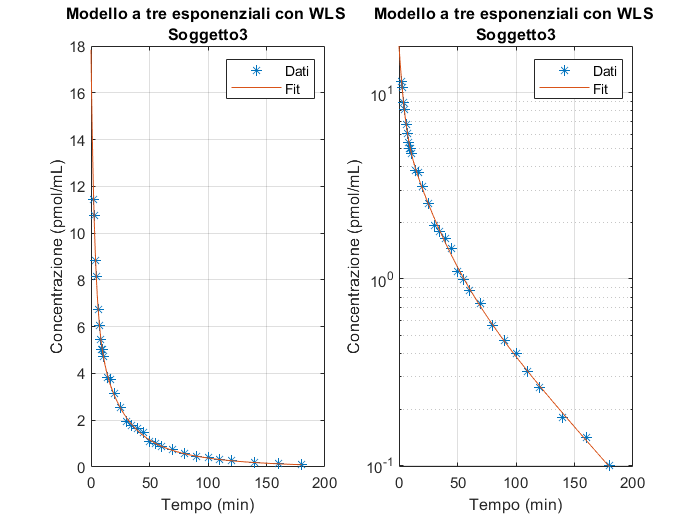

figure(12);
% Plot scala naturale
t_ls = [0:0.001:t1(end)];
plot(t,c,"*"); hold on, plot(t_ls,x3_wls(1)*exp(-x3_wls(2)*t_ls)+x3_wls(3)*exp(-x3_wls(4)*t_ls)+x3_wls(5)*exp(-x3_wls(6)*t_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title(["Modello a tre esponenziali con WLS ",selectedSogg]), legend("Dati","Fit"); 
% Plot scala logaritmica
subplot(1,2,1,gca)
subplot(1,2,2), semilogy(t,c,"*"); hold on,  semilogy(t_ls,x3_wls(1)*exp(-x3_wls(2)*t_ls)+x3_wls(3)*exp(-x3_wls(4)*t_ls)+x3_wls(5)*exp(-x3_wls(6)*t_ls)), 
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on, 
title(["Modello a tre esponenziali con WLS ",selectedSogg]), legend("Dati","Fit");

disp(["Parametri LS 3-exp: A = ",num2str(x3_wls(1))," alpha = ",num2str(x3_wls(2))," B = ",num2str(x3_wls(3))," beta = ",num2str(x3_wls(4)), ...
      " C = ",num2str(x3_wls(5))," gamma = ",num2str(x3_wls(6))]); % Stampa dei parametri del fitting

  Columns 1 through 9

    "Parametri LS 3-ex…"    "11.0191"    " alpha = "    "0.32564"    " B = "    "4.9814"    " beta = "    "0.053222"    " C = "

  Columns 10 through 12

    "1.8356"    " gamma = "    "0.016309"



Analisi dei residui.

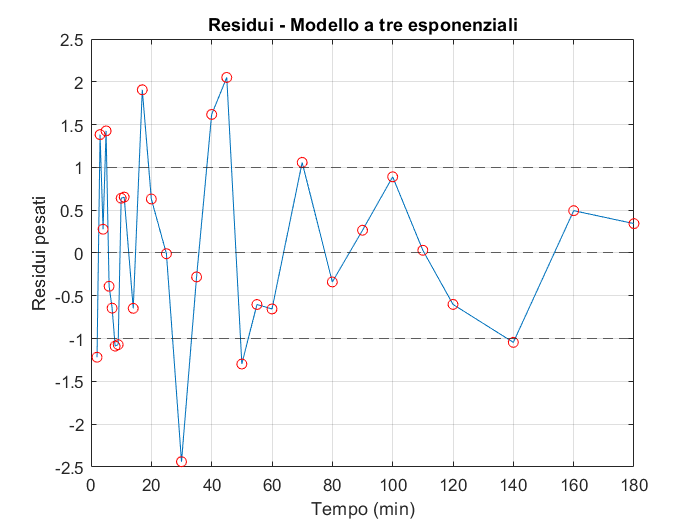

figure(13);
plot(t,residual3_wls,"-o","MarkerIndices",1:1:length(residual3_wls),"MarkerEdgeColor","r"), grid on, 
xlabel("Tempo (min)"), ylabel("Residui pesati"), ylim([-2.5,2.5]), title("Residui - Modello a tre esponenziali"),
yline(-1,"--"); yline(1,"--"); yline(0,"--");

Per valutare la precisione delle stime numeriche dei parametri, calcolo la matrice di correlazione (a partire dalla matrice di covarianza). 

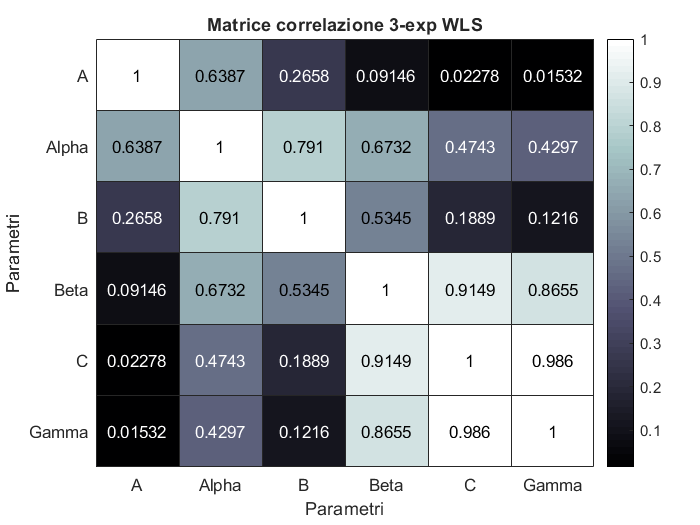

sigma_pt3_wls = inv(full(jacobian3_wls)'*full(jacobian3_wls)); % Matrice di covarianza

% Matrice di correlazione
cor3_wls = zeros(length(sigma_pt3_wls));

for i = 1:length(sigma_pt3_wls)
    for j = 1:length(sigma_pt3_wls)
        cor3_wls(i,j) = sigma_pt3_wls(i,j)/sqrt(sigma_pt3_wls(i,i)*sigma_pt3_wls(j,j));
    end
end

figure(19);
xvalues = {'A','Alpha','B','Beta','C','Gamma'};
yvalues = {'A','Alpha','B','Beta','C','Gamma'};
h = heatmap(xvalues,yvalues,cor3_wls,"Colormap",bone);

h.Title = 'Matrice correlazione 3-exp WLS';
h.XLabel = 'Parametri';
h.YLabel = 'Parametri';

Calcolo indicatori.

aic3_wls = (resnorm3_wls+2*6)/length(c);  % AIC

% ICOMP
f3_wls = full(jacobian3_wls)'*full(jacobian3_wls); % Matrice informazione di Fischer
lambda_a1 = trace(f3_wls)/6;
lambda_g1 = det(f3_wls)^(1/6);
icomp3_wls = resnorm3_wls+2*(6/2*log(lambda_a1/lambda_g1));

disp(["AIC = ",num2str(aic3_wls),"ICOMP = ",num2str(icomp3_wls)]);

    "AIC = "    "1.4974"    "ICOMP = "    "83.7848"



Calcolo CV.

cv3_1 = 100*sqrt(sigma_pt3_wls(1,1))/x3_wls(1);
cv3_2 = 100*sqrt(sigma_pt3_wls(2,2))/x3_wls(2);
cv3_3 = 100*sqrt(sigma_pt3_wls(3,3))/x3_wls(3);
cv3_4 = 100*sqrt(sigma_pt3_wls(4,4))/x3_wls(4);
cv3_5 = 100*sqrt(sigma_pt3_wls(5,5))/x3_wls(5);
cv3_6 = 100*sqrt(sigma_pt3_wls(6,6))/x3_wls(6);

cv3 = [cv3_1,cv3_2,cv3_3,cv3_4,cv3_5,cv3_6]';
cv3_wls = table(x3_wls',cv3,'VariableNames',{'Parametri','CV'});
disp(cv3_wls);

    Parametri      CV  
    _________    ______

      11.019     10.591
     0.32564      14.46
      4.9814     7.7487
    0.053222     11.365
      1.8356     15.758
    0.016309     6.5548

